# Setting plot axis limits

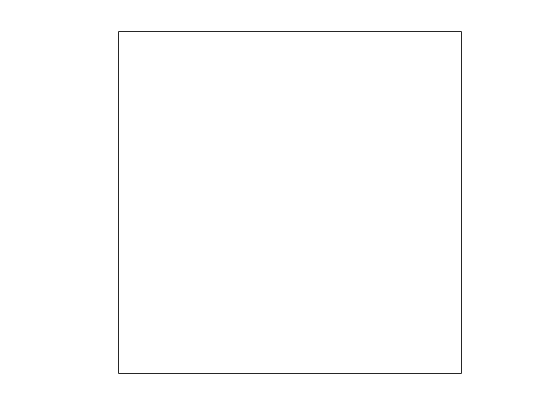

nlatlim = [53.68, 54.01];
nlonlim =[2.18, 2.81];
axesm('MapProjection','mercator','MapLatLimit',[53.68, 54.01], 'MapLonLimit',nlonlim)

# getting upper and lower bound coordinates in degrees from shape file of horn shore 3

% reading hornsea shapefile
S = shaperead('horn3shape.shp');

min_long_x = S.BoundingBox(1,1) % in deg

min_long_x = 2.1974

max_long_x = S.BoundingBox(2,1) % in deg

max_long_x = 2.7933

min_lat_y = S.BoundingBox(1,2) % in deg

min_lat_y = 53.6895

max_lat_y = S.BoundingBox(2,2) % in deg

max_lat_y = 54.0011

## Plotting positions as scatter

numT=4;
hubHeight = 160;
[florisTurbPos,costTurbPos] = initTurbPos2(numT, hubHeight);

## Plotting shape file over bathymetry data

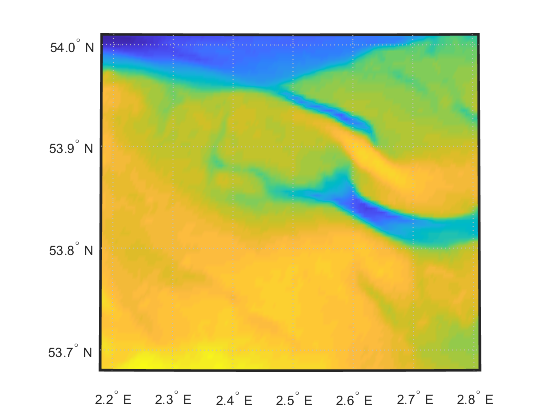

% bathymetry data map 
[A,R] = readgeoraster('hsb.tif','OutputType','double');
%Create a map. First, create map axes by specifying the latitude and longitude limits of the data. Then, display the data as a surface using the geoshow function. Apply a colormap appropriate for elevation data using the demcmap function.
latlim = R.LatitudeLimits;
lonlim = R.LongitudeLimits;


% cropping bathymetry data to fit map better
[B,RB] = geocrop(A,R,nlatlim,nlonlim);

usamap(nlatlim,nlonlim);
geoshow(B,RB,'DisplayType','surface');

%hold on

## plotting shape outline

% use: hornshape = S.Geometry to see what bits r called
% boundary coordinates
x1 = S.X

x1 =     2.7483    2.7933    2.7933    2.4121    2.3954    2.3954    2.1974    2.1974    2.2263    2.5455    2.6813    2.7483       NaN


y1 = S.Y

y1 =    53.8159   53.6895   53.6895   53.8065   53.8075   53.8075   53.9896   53.9896   53.9887   53.9785   54.0011   53.8159       NaN


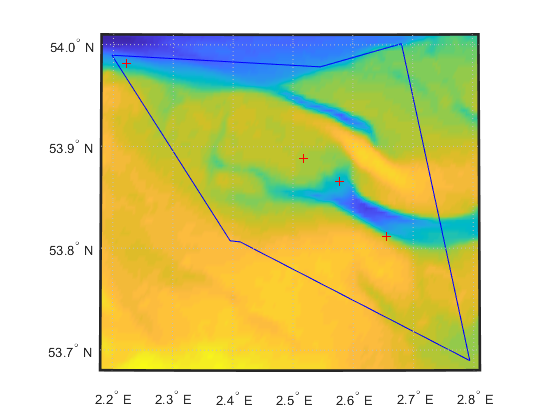

% showing shape on the map
geoshow(S.Y,S.X);

%% P

latPos = costTurbPos(:,1);
longPos = costTurbPos(:,2);

for i=1:length(latPos)
    p = geopoint(latPos(i),longPos(i));
    geoshow(p,'DisplayType','Point');

    if i == 1
        hold on
    end
end


hold off 